# **Fase 4: Diseño del regulador PID**

**Parámetros iniciales:**

clear

Ts = 0.035;
ts = 1.12;
errp = 0;
BoG = zpk([],0.8752, 0.0251, Ts)


BoG =
 
    0.0251
  ----------
  (z-0.8752)
 
Sample time: 0.035 seconds
Discrete-time zero/pole/gain model.
Model Properties


Con oscilación nula para entrada escalón.


$$BoG(z) = \frac{0.0251}{z - 0.8752} [\frac{m/s}{V}]$$


### **Ejercicio 15: Calcular la FdeT del regulador PID.**

**Módulo del polo buscado:**

ks = round(ts/Ts);
mod_p = exp(-3/ks)

mod_p =    0.910510361380034



$$|p| = 0.9105$$


Como tiene oscilación nula, el polo solo puede ser:


$$p = 0.9105$$


**Regulador P:**

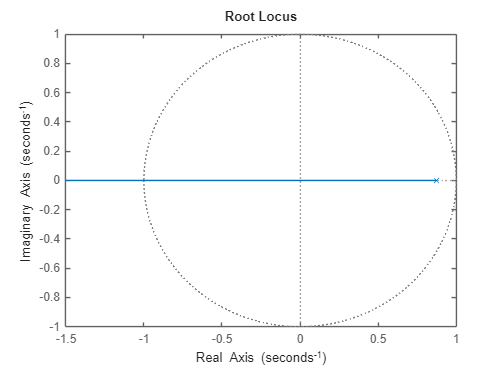

rlocus(BoG)

No puede ser un regulador P ya que no hay ninguna kp para la que el polo sea el buscado.

**Regulador I:**

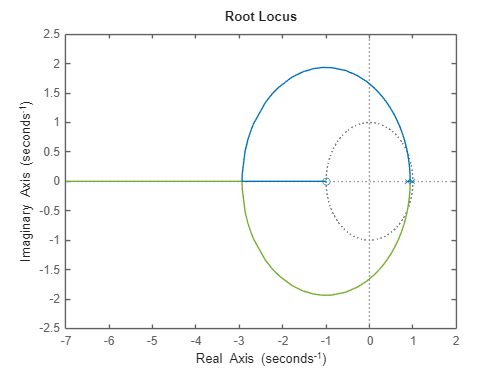

Fz = zpk(-1, [0.8752 1], 1, Ts);
rlocus(Fz)

No puede ser un regulador I ya que el polo no sería dominante.

**Regulador PI:**

En primer lugar, el cero elimina el polo no dominante para asegurarnos de que el polo dominante es el que vale lo buscado. Eso se consigue con un regulador:


$$F(z) = K \cdot \frac{z - 0.8752}{z - 1}$$


Ahora falta encontrar el valor de k para el que el polo vale 0.9105. Para ello aplicamos la condición modular:


$$|K| = \frac{1}{|X|} = |\frac{z - 1}{0.0251}| = |\frac{0.9105 - 1}{0.0251}| = 3.5657$$


Finalmente, la función del regulador queda:


$$F(z) = 3.5657 \cdot \frac{z - 0.8752}{z - 1}$$



$$F(z) = \frac{3.5657 - 3.1207z^{-1}}{1 - z^{-1}}$$



$$a[k] = a[k-1] + 3.5657e[k] - 3.1207e[k-1]$$


**Parámetros de sintonía:**


$$Ti = \frac{Ts}{2} \cdot \frac{1 + c}{1 - c} = \frac{0.035}{2} \cdot \frac{1 + 0.8752}{1 - 0.8752} = 0.2629 s$$



$$Kp = K \cdot \frac{2Ti}{2Ti + T} = 3.5657 \cdot \frac{2 \cdot 0.2629}{2 \cdot 0.2629 + 0.035} = 3.3432$$



$$Ki = \frac{Kp}{Ti} = \frac{3.3432}{0.2629} = 12.7166$$



$$q_0 = Kp + \frac{Ki \cdot T}{2} = 3.5657$$



$$q_1 = -Kp + \frac{Ki \cdot T}{2} = -3.1207$$



$$F(z) = \frac{3.5657z^2 - 3.1207z}{z(z - 1)}$$


K = 3.5657;
Ti = (Ts/2) * ((1+0.8752)/(1-0.8752));
Kp = K * (2*Ti)/(2*Ti+Ts);
Ki = Kp/Ti;
q0 = Kp + (Ki*Ts)/2;
q1 = -Kp + (Ki*Ts)/2;
Fz = tf([q0 q1 0], [1 -1 0], Ts)


Fz =
 
  3.566 z^2 - 3.121 z
  -------------------
        z^2 - z
 
Sample time: 0.035 seconds
Discrete-time transfer function.
Model Properties


### Ejercicio 16: Calcular la FdeT del sistema y obtener los polos.

Mz = minreal(feedback(series(Fz, BoG), 1))


Mz =
 
   0.089499
  ----------
  (z-0.9105)
 
Sample time: 0.035 seconds
Discrete-time zero/pole/gain model.
Model Properties


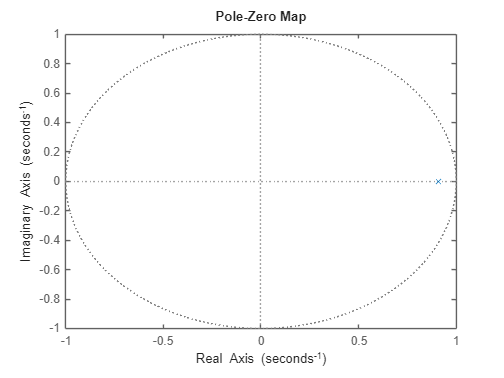

pzplot(Mz)

p = pole(Mz)

p =    0.910500930000000



$$M(z) = \frac{0.0895}{z - 0.9105}$$


### **Ejercicio 17: Caracterizar en régimen transitorio y permanente la salida a entradas escalón **±** 1 m/s.**

**Regimen permanente:**

Entrada escalón +1m/s:


$$c(\infty) = R \cdot \lim_{z \to 1} \frac{0.0895}{z - 0.9105} = 1 \cdot 1 = 1 m/s$$


Entrada escalón -1m/s:


$$c(\infty) = R \cdot \lim_{z \to 1}  \frac{0.0895}{z - 0.9105} = -1 \cdot 1 = -1 m/s$$


**Régimen transitorio:**

Polo real simple -> Sistema sobreamortiguado.


$$p = 0.9105$$



$$ks = \frac{-3}{ln(|p|)} = \frac{-3}{ln(0.9105)} = 32$$



$$ts = ks \cdot Ts = 1.12 s$$
 

### Ejercicio 18: Acción de control y velocidad de la escalera en régimen permanente para **entradas escalón **±** 1 m/s.**


$$erpp = \frac{R}{1 + ko[CA]} = \frac{R}{1 + ko[F \cdot BoG \cdot H]}$$



$$c(\infty) = R - errp$$



$$A(\infty) = \frac{c(\infty) + Perturbacion}{ko[BoG]}$$


**Velocidad de la escalera y Acción de control con 0 personas:**

pert = 0;
g_inf = dcgain(BoG);

Entrada +1 m/s:

R = 1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =      1


a_inf = (c_inf + pert)/g_inf

a_inf =    4.972111553784861


Entrada -1 m/s:

R = -1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =     -1


a_inf = (c_inf + pert)/g_inf

a_inf =   -4.972111553784861


**Velocidad de la escalera y Acción de control con 5 personas:**

pert = 0.1;
g_inf = dcgain(BoG);

Entrada +1 m/s:

R = 1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =      1


a_inf = (c_inf + pert)/g_inf

a_inf =    5.469322709163347


Entrada -1 m/s:

R = -1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =     -1


a_inf = (c_inf + pert)/g_inf

a_inf =   -4.474900398406374


**Velocidad de la escalera y Acción de control con 10 personas:**

pert = 0.2;
g_inf = dcgain(BoG);

Entrada +1 m/s:

R = 1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =      1


a_inf = (c_inf + pert)/g_inf

a_inf =    5.966533864541832


Entrada -1 m/s:

R = -1;
erpp = R/(1 + dcgain(series(Fz, BoG)));
c_inf = R-errp

c_inf =     -1


a_inf = (c_inf + pert)/g_inf

a_inf =   -3.977689243027889


**Conclusión:**

Cuanto más personas se suben a la escalera, mayor es el peso que ejercen: 

- En el caso de la subida, la señal de acción aumenta dado que se necesita más energía para mover la escalera y que se mantenga constante la velocidad. 

- En el caso de la bajada, cuando mayor es el peso, más facilidad tiene la escalera para bajar, por lo que la señal de control disminuye (en módulo) para que pueda mantenerse constante la velocidad. 